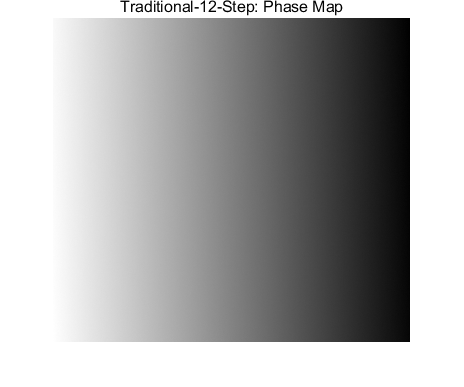

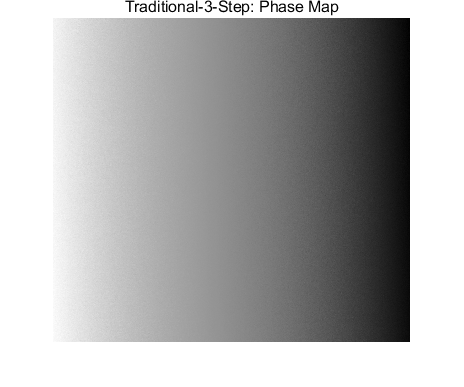

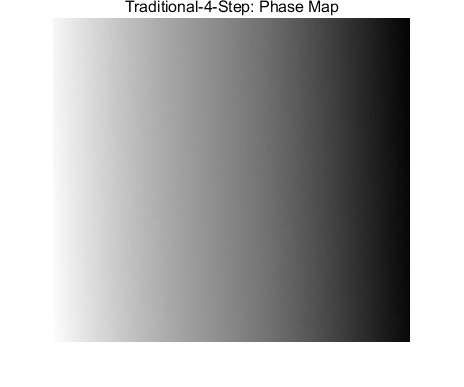

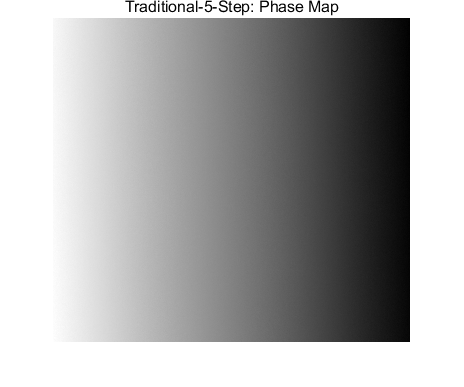

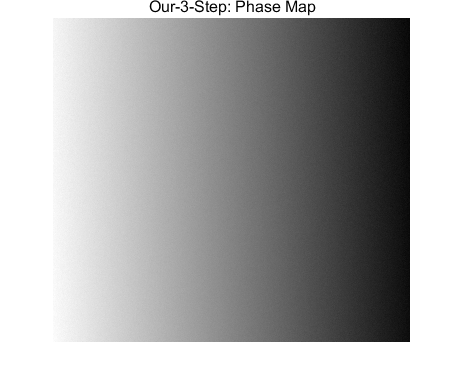

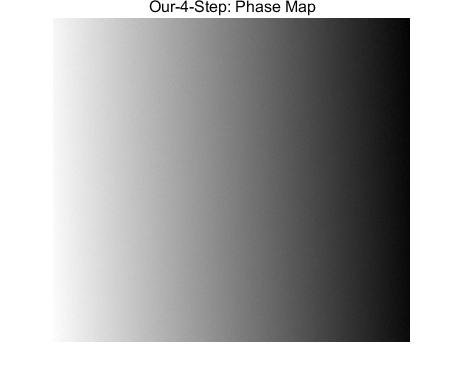

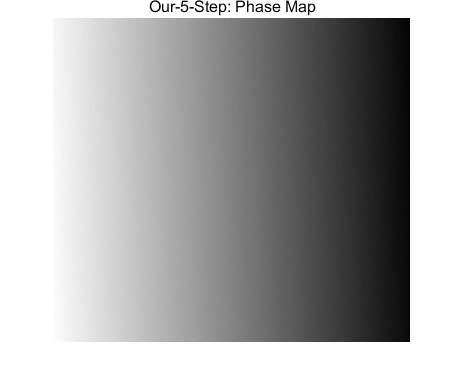

clc; close all; clear;
root_path='..\Data\';
Target_name='Plane-';
method_name={'Traditional-12-Step','Traditional-3-Step','Traditional-4-Step','Traditional-5-Step',...
             'Our-3-Step','Our-4-Step','Our-5-Step'};
for i=1:length(method_name)
    Method_name{i}=[Target_name,method_name{i}];
end
Step_name=[12, 3, 4, 5, 3, 4, 5];
Flag_Ours=[ 0, 0, 0, 0, 1, 1, 1];
Method_number=length(Method_name);
N2=12;
c=10;   % C is a scaling factor that makes the number of scans as integer as possible.
k2=1:N2;
k2_ideal_scanning_number=c*(cos(2*(k2-1)*pi/N2)+1);  % +1To make the number of scans not negative. A total of c * N2 patterns were scanned without considering rounding errors.
k2_scanning_number=round(k2_ideal_scanning_number);
k2_difference=k2_ideal_scanning_number-k2_scanning_number;
c2=N2*c/2; c3=0;  % C is a scaling factor that makes the number of scans as integer as possible.
for k2=1:N2
    c2=c2-cos(2*(k2-1)*pi/N2)*k2_difference(k2);
    c3=c3+sin(2*(k2-1)*pi/N2)*k2_difference(k2);
end
%%% data access
for id_method = 1:Method_number
    N=Step_name(id_method);
    numerator=0;
    denominator=0;
    for k=1:N
        path=[root_path,Method_name{id_method},'\1_', num2str(k),'.bmp'];
        Img=imread(path);
        Img=im2double(Img);
        if Flag_Ours(id_method)==0
            numerator=numerator+Img*sin(2*(k-1)*pi/N);
            denominator=denominator+Img*cos(2*(k-1)*pi/N);
        else
            numerator=numerator-(c3*cos(2*(k-1)*pi/N)-c2*sin(2*(k-1)*pi/N))*Img; %%注意为减法
            denominator=denominator+(c2*cos(2*(k-1)*pi/N)+c3*sin(2*(k-1)*pi/N))*Img;
        end
    end
    phi_base_freq=-atan2(numerator,denominator)+pi;   %range: 0-2*pi
    figure;imshow(phi_base_freq,[]);title([method_name{id_method},': Phase Map'],'FontSize',9.5);
    path=[root_path,Method_name{id_method},'\','Phase.mat']; 
    save(path, 'phi_base_freq');
end

%%%%%% error analysis
img_width=648; img_height=588; 
img_phase = zeros(img_height,img_width,Method_number); 
Phase_error_2D = zeros(img_height,img_width,Method_number-1); 
Phase_error_2D_noabs = zeros(img_height,img_width,Method_number-1); 
%%% load phase map
for id_method = 1:Method_number
    temp=load([root_path,Method_name{id_method},'\','Phase.mat']);
    img_phase(:,:,id_method)=temp.phi_base_freq;
end
%%% phase error
for id_method = 2:Method_number
    Phase_error_2D_noabs(:,:,id_method-1)=img_phase(:,:,id_method)-img_phase(:,:,1);
    Phase_error_2D(:,:,id_method-1)=abs(img_phase(:,:,id_method)-img_phase(:,:,1));
    Phase_error_1D = reshape(Phase_error_2D(:,:,id_method-1),[1,img_height*img_width]);
    mean_phase_error(id_method-1)=mean(Phase_error_1D);
    RMSE_phase_error(id_method-1)=sqrt(mean(Phase_error_1D.^2));
    std_phase_error(id_method-1)=std(Phase_error_1D);
end

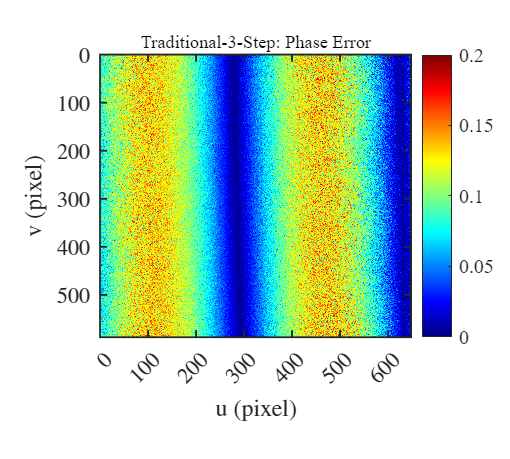

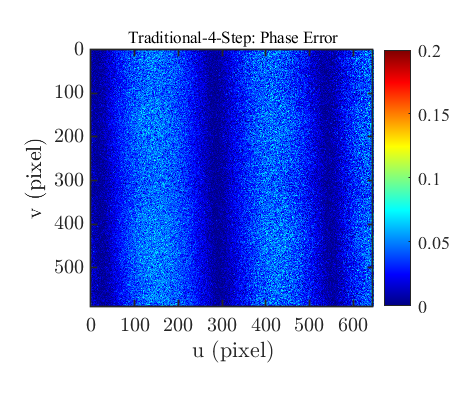

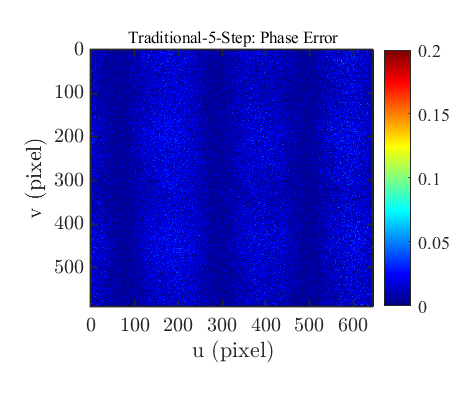

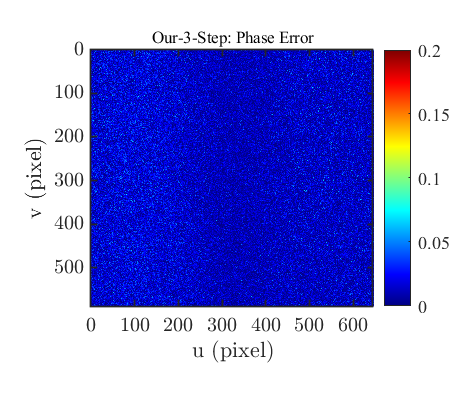

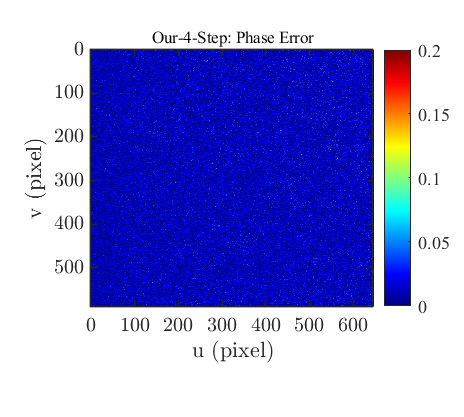

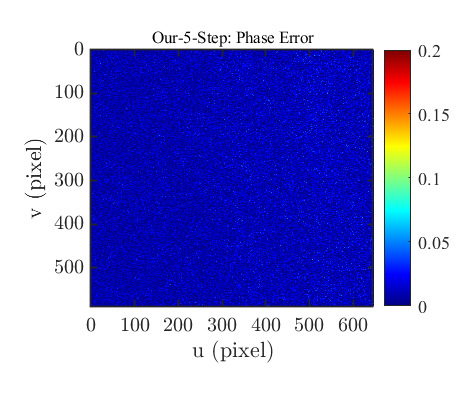

%%%%%%%%%%%%%%%%%%%% Draw a two-dimensional phase error distribution map
for id_method = 1:Method_number-1
    errormap=Phase_error_2D(:,:,id_method);
    fig=figure;ax = axes(fig);imagesc(errormap);colormap(jet); caxis([0 0.2]); colorbar; 
    adjust_fig(fig, ax, 0, 'u (pixel)', 'v (pixel)');
    axis equal; xlim([0,img_width]);ylim([0,img_height]);ax.XMinorTick = 'off'; ax.YMinorTick = 'off'; grid off;
    set(gca,'xtick',0:100:680); set(gca,'ytick',0:100:700);
    title([method_name{id_method+1},': Phase Error'],'FontSize',10);
    hold off; 
end

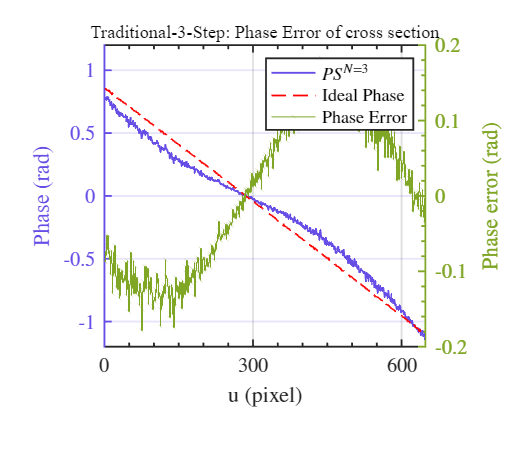

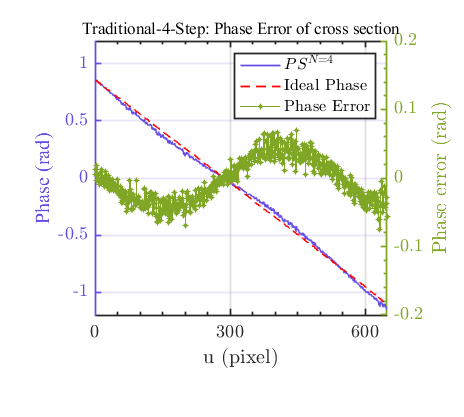

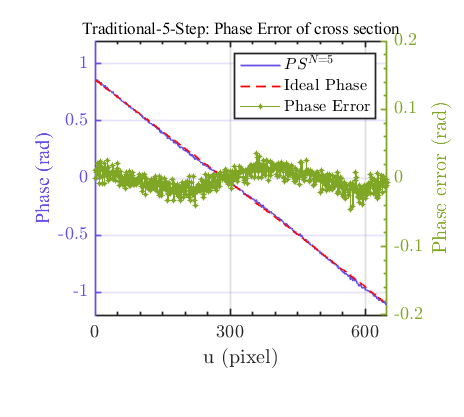

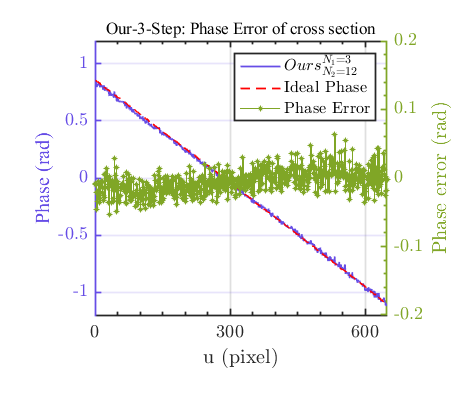

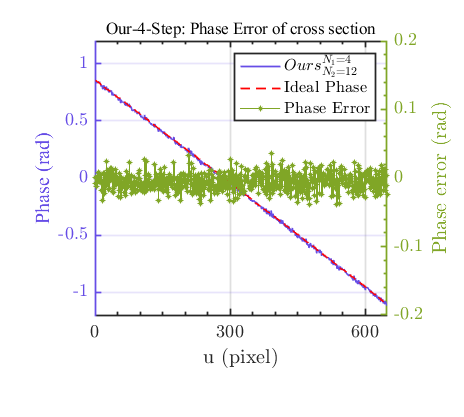

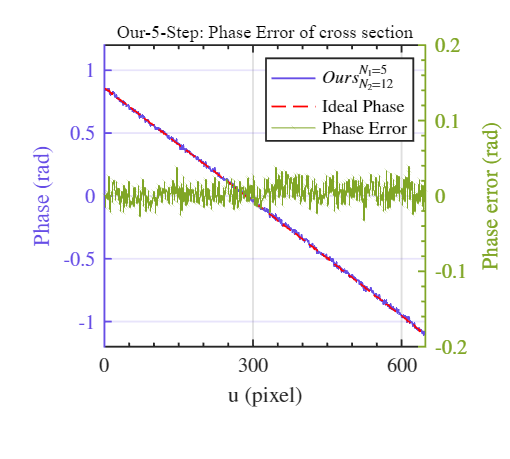

%%%%%%%%%%%%%%%%%%% CrossLine diagram
Row_instrest=300;
for id_method=1:Method_number-1
    fig=figure;
    ax = axes(fig);
    colororder([0.40 0.30 0.90; 0.50 0.65 0.15]);
    %%% Phase map
    yyaxis left; 
    plot(img_phase(Row_instrest,:,id_method+1)-pi,...
         'Marker','none','LineStyle','-','LineWidth',1);
    hold on;plot(img_phase(Row_instrest,:,1)-pi,...
         'Marker','none','LineStyle','--','LineWidth',1,'Color','r');
    ylabel('Phase (rad)'); ylim([-1.2 1.2]); 
    %%% phase error diagram
    yyaxis right; 
    hold on;stairs(Phase_error_2D_noabs(Row_instrest,:,id_method),...
        'Marker','*','MarkerSize',3,'LineStyle','-','LineWidth',0.01);
    ylabel('Phase error (rad)'); ylim([-0.2 0.2]);  
    xlabel('u (pixel)');set(gca,'xtick',0:300:600);xlim([0 img_width]);
    %%%% Picture Properties and Sizing
    if id_method<4
        Step_string='$P{S^{N = 3}}$';
        label = legend(['$P{S^{N =',num2str(id_method+2),'}}$'],'Ideal Phase','Phase Error','Interpreter','latex');
    else 
        label = legend(['$Ours_{{N_2} = 12}^{{N_1} =',num2str(id_method-1),'}$'],'Ideal Phase','Phase Error','Interpreter','latex');
    end
    label.ItemTokenSize= [24,24];
    adjust_fig(fig, ax, 0, 'u (pixel)','Phase error (rad)'); 
    yyaxis right; 
    set(get(gca,'YLabel'),'FontSize',13); 
    set(gca,'FontSize',11); 
    yyaxis left;
    set(get(gca,'YLabel'),'FontSize',13'); 
    set(gca,'FontSize',11); 
    outerpos = ax.OuterPosition;
    ti = ax.TightInset;
    left = outerpos(1)+1*ti(1) ;
    bottom = outerpos(2)+1.5*ti(2) ;
    ax_width = outerpos(3) - 0.5*(ti(1) + ti(3));
    ax_height = outerpos(4) - 1.8*(ti(2) + ti(4));
    ax.Position = [left bottom ax_width ax_height]; 
    title([method_name{id_method+1},': Phase Error of cross section'],'FontSize',10);
end